close all;

myGuidController = GUID_Controller;

theFiles = [];
for j = 1:3
    miniPattern = "C:\Users\Courtney\source\repos\ThesisProject\" + ...
        "Data\Session01_ManipulatedData\SavedCycles_Resampled\" + ...
        "Session01_Exp_F1_*_SavedCycle_"+j+"*.mat";
    
    % collect the files
    theFiles = [theFiles; dir(miniPattern)];
    
end

figure;
hold on;
set( gca, 'Color', 'None', 'XColor', 'White', 'YColor', 'White') ;
 set( gcf, 'Color', 'White', 'Unit', 'Normalized', ...
    'Position', [0.1,0.1,0.4,0.6] ) ;

axes( 'Position', [0.06, 0.1, 0.9, 0.7] ) ;
% set(gca,'xtick',[], 'xticklabel',[], 'ytick',[], 'yticklabel',[])
xticks(-50:0.1:50)
yticks(-50:0.1:50)
xlabel('X')
ylabel('Y')
set(gca, 'xticklabel',[], 'yticklabel',[])
% set(gca,')
% xticklabels('off')
axis equal;
hold on;
% do for every file in the files
for k = 1:length(theFiles)

    currFileName = theFiles(k).name;
    withFolders = "Data\Session01_ManipulatedData\SavedCycles_Resampled\"+currFileName;
    fprintf(1, 'Now reading %s\n', currFileName)
    resampledData = load(withFolders).tXYZ;
    
    if (k == 1)
            plot(resampledData(:,2), resampledData(:,3), 'LineWidth',0.3, 'Color','#808080')

    else
            plot(resampledData(:,2), resampledData(:,3), 'LineWidth',0.3, 'Color','#808080','HandleVisibility','off')

    end

end

Now reading Session01_Exp_F1_001_SavedCycle_1_Resampled.mat
Now reading Session01_Exp_F1_001_SavedCycle_2_Resampled.mat
Now reading Session01_Exp_F1_001_SavedCycle_3_Resampled.mat


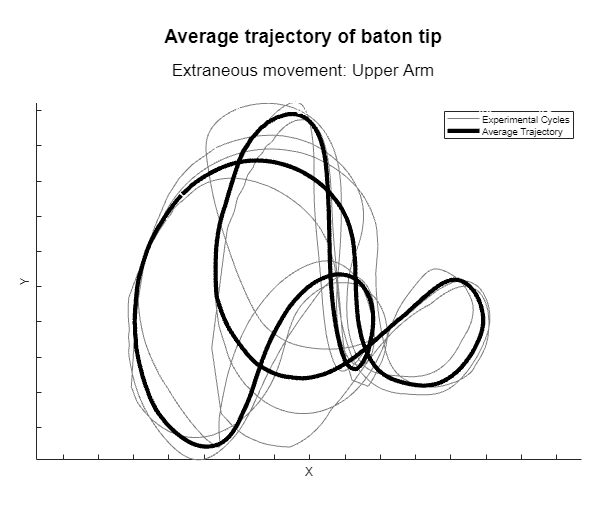


averageFile = "Data\Session01_ManipulatedData\SavedCycles_Resampled\Session01_Exp_F1_All_Resampled_Average.mat";
resampledAverageData = load(averageFile).tXYZ_Average;
plot(resampledAverageData(:,2), resampledAverageData(:,3), 'LineWidth',4, 'Color','k')


% set title
niceTitle = {"Average trajectory of baton tip","Extraneous movement: Upper Arm"};

% legend(['','',"Experimental Cycles","Average Trajectory"])

legend(["Experimental Cycles","Average Trajectory"])

axes( 'Position', [0, 0.8, 1, 0.2] ) ;
set( gca, 'Color', 'None', 'XColor', 'White', 'YColor', 'White' ) ;
text( 0.5, 0.66, niceTitle{1}, 'FontSize', 18', 'FontWeight', 'bold', ...
  'HorizontalAlignment', 'Center', 'VerticalAlignment', 'middle' ) ;
text( 0.5, 0.33, niceTitle{2}, 'FontSize', 16', 'FontWeight', 'normal', ...
  'HorizontalAlignment', 'Center', 'VerticalAlignment', 'middle' ) ;


% get graph details
graphDetails = sprintf('60bpm_mf_44path_Normal_SplitCycles_TimeBased_Upper_Arm');

% save in GUID directory, get GUID
folderToSaveIn = 'Visualisations/Session01_Resampled_Average_Figures';   % Your destination folder
descriptionToUse = sprintf("Details: %s. Script used: %s.  Dataset used: %s. File Location: %s. Date Generated: %s", graphDetails, mfilename, currFileName, folderToSaveIn, datetime('now'));
GUIDToAppend = myGuidController.updateGuidDirectory(descriptionToUse).currGUID;



% get all open figures
figureSaveTitle = sprintf('%s_%s.fig', graphDetails, GUIDToAppend);
pngSaveTitle = sprintf('%s_%s.png', graphDetails, GUIDToAppend);

% pause(10)
% % save all figures
% FigList = findobj(allchild(0), 'flat', 'Type', 'figure');
% myGuidController.saveFigures(graphDetails, GUIDToAppend, FigList, folderToSaveIn);

